# Training and test document for object detection

## Created by: Alejandro Boadella Aguado (EETAC-UPC)

*References: MATLAB sources and examples.*

Location of the files and labeled ground-truth data.

photos2 = load("C:\Users\Alex\Desktop\photos2\photos2.mat");
gTruth2 = photos2.gTruth;

photos3 = load("C:\Users\Alex\Desktop\photos3\photos3.mat");
gTruth3 = photos3.gTruth;

photos4 = load("C:\Users\Alex\Desktop\photos4\photos4.mat");
gTruth4 = photos4.gTruth;

photos5 = load("C:\Users\Alex\Desktop\photos5\photos5.mat");
gTruth5 = photos5.gTruth;

photos6 = load("C:\Users\Alex\Desktop\photos6\photos6.mat");
gTruth6 = photos6.gTruth;

photos7 = load("C:\Users\Alex\Desktop\photos7\photos7.mat");
gTruth7 = photos7.gTruth;

photos8 = load("C:\Users\Alex\Desktop\photos8\photos8.mat");
gTruth8 = photos8.gTruth;

photos9 = load("C:\Users\Alex\Desktop\photos9\photos9.mat");
gTruth9 = photos9.gTruth;

photos10 = load("C:\Users\Alex\Desktop\rest_photos\rest_photos.mat");
gTruth10 = photos10.gTruth;

Combination of ground-truth and generation of anchors for heading of the YOLOv4 "tiny version" and ACF.

[imList,boxLabels]=objectDetectorTrainingData([gTruth2 gTruth3 gTruth4 gTruth5 gTruth6 gTruth7 gTruth8 gTruth9 gTruth10]);
TrainingData=combine(imList,boxLabels);
className = "car";

numAnchors = 6;
[anchors,meanIoU] = estimateAnchorBoxes(TrainingData,numAnchors);
area = anchors(:, 1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:) anchors(4:6,:) };

In case of the big version of YOLOv4 is requested use this code for anchors. 

The big version has more heads (anchors) in the structural part as explained in the project.

numAnchors = 9;
[anchors,meanIoU] = estimateAnchorBoxes(TrainingData,numAnchors);
area = anchors(:, 1).*anchors(:,2);
[~,idx] = sort(area,"descend");
anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:) anchors(4:6,:) anchors(7:9,:)};

ACF detector trained 

detector = trainACFObjectDetector(TrainingData,NumStages=10)

Code to obtain the YOLOv4 detector (using the tiny version)

detector = yolov4ObjectDetector("tiny-yolov4-coco",className,anchorBoxes);

Options for training procedure.

options = trainingOptions('sgdm',...
          InitialLearnRate = 0.0001,...
          Verbose = true,...
          MiniBatchSize = 16,...
          MaxEpochs = 260,...
          VerboseFrequency = 30, ...
          l2Regularization = 0.0005, ...
          Shuffle ='every-epoch', ...
          ResetInputNormalization=true, ...
          ExecutionEnvironment='gpu');

Training of the detector

[detector2,info] = trainYOLOv4ObjectDetector(TrainingData,detector,options);

Load saved detectors, created before.

load AI3.mat
load ACF3.mat

Load new images to evaluate detector.

photos1 = load("C:\Users\Alex\Desktop\photos1\photos1.mat");
gTruth1 = photos1.gTruth;
[imList,boxLabels]=objectDetectorTrainingData(gTruth1);

Load new and old images to evaluate detector (needs previous codes to be activated)

[imList,boxLabels]=objectDetectorTrainingData([gTruth1 gTruth2 gTruth3 gTruth4 gTruth5 gTruth6 gTruth7 gTruth8 gTruth9 gTruth10]);

Detection

results = detect(detector,imList);

Evaluation of the results (using an overalp of 0.35 out of 1)

Overlap=0.35;
[ap, recall, precision] = evaluateDetectionPrecision(results, boxLabels,Overlap);
[am, fppi, missRate] = evaluateDetectionMissRate(results, boxLabels,Overlap);

figure(1)
plot(recall, precision);
grid on
title(sprintf('Average precision = %f', ap))
xlabel('Recall')
ylabel('Precision')
xlim([0 1.1])
ylim([0 1.1])

figure(2)
loglog(fppi, missRate);
grid on
title(sprintf('log Average Miss Rate = %f', am))
xlabel('Fppi')
ylabel('MissRate')
xlim([0 1.1])
ylim([0 1.1])

Test the detector on an image (use this code or the following one, both are pretty similar)

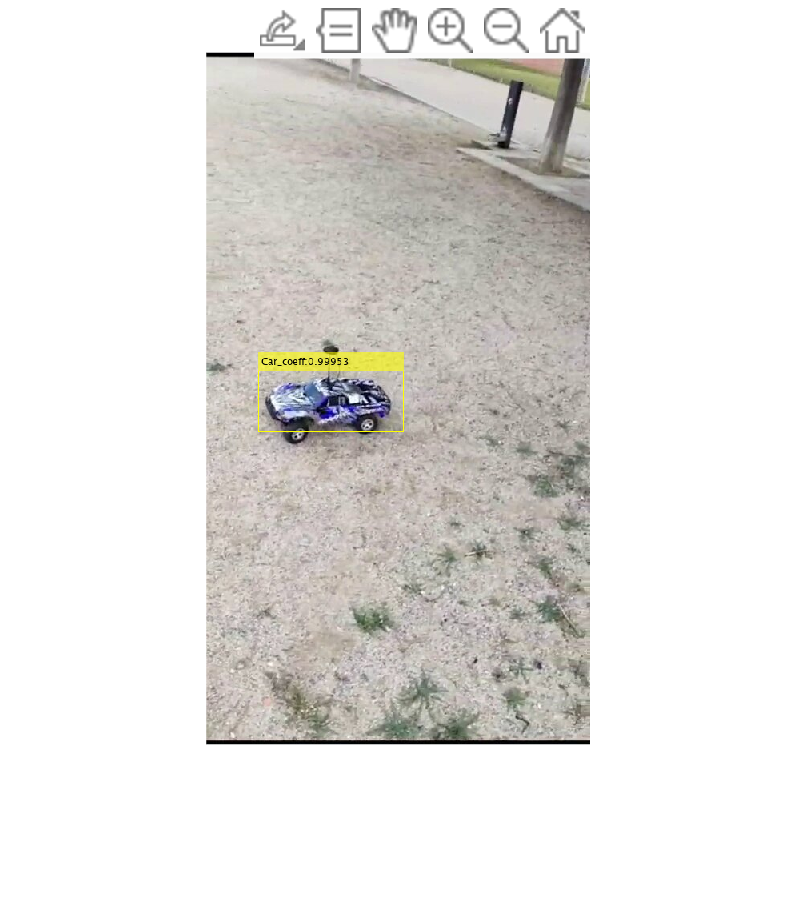

img = imread("C:\Users\Alex\Desktop\photos4\VID-20231114-WA0006_060.png");
[bboxes,scores] = detect(detector2,img);
[selectedBbox,selectedScore] = selectStrongestBbox(bboxes,scores,"NumStrongest",1);
frameLabeled=insertObjectAnnotation(img,"rectangle",selectedBbox,"Car_coeff:"+ selectedScore);
figure
imshow(frameLabeled)

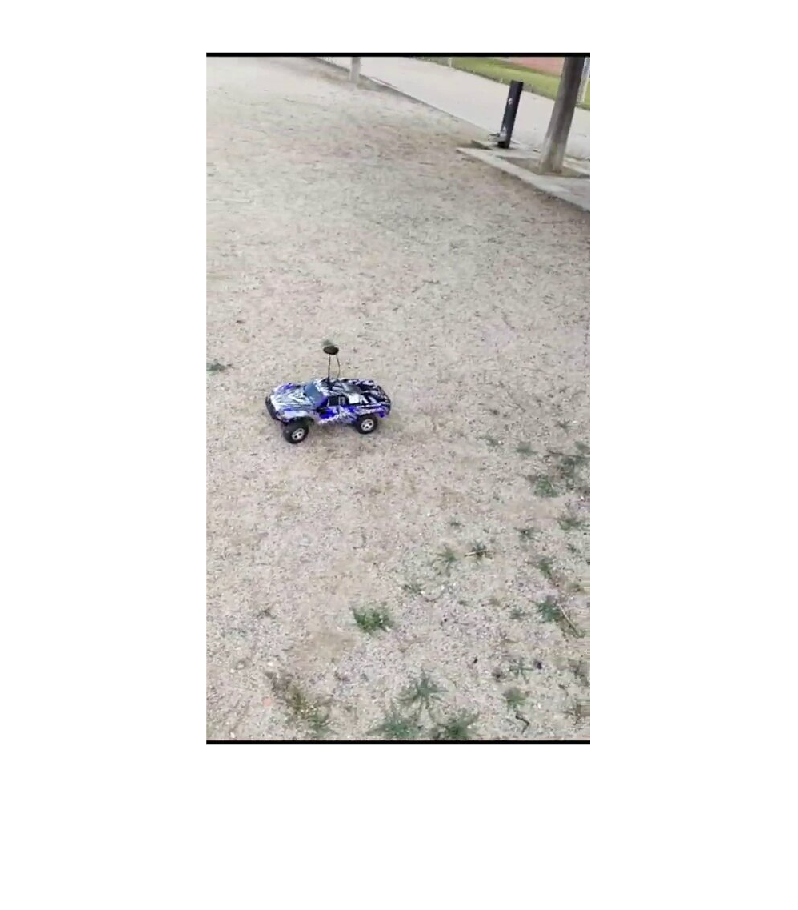

img = imread("C:\Users\Alex\Desktop\photos4\VID-20231114-WA0006_060.png");
[bboxes,scores] = detect(detector,img);
bboxes=bboxes(scores>15,:);
scores=scores(scores>15,:);
[selectedBbox,selectedScore] = selectStrongestBbox(bboxes,scores,"NumStrongest",1);
frameLabeled=insertObjectAnnotation(img,"rectangle",selectedBbox,"Car_coeff:"+ selectedScore);

figure
imshow(frameLabeled)